# **Getting started with  consensus for dense ODM maps**

**Generate data**

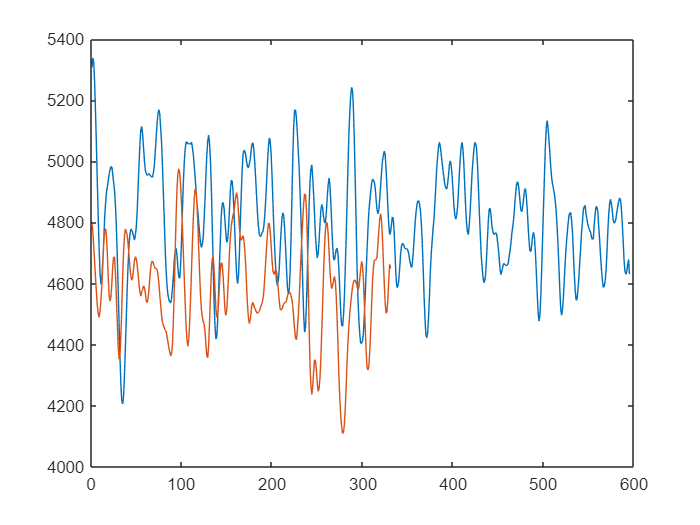

% Schematics of de-novo assembly problem using DNA barcodes.
rng('default')

snr = 2; 
N = 30;
import Core.load_synth_data;
[bgAll, bG, synthStr, synthStr2, theoryStruct] = load_synth_data(N,2.72,450,100,snr,0.05,1,2000,150);

sets.minOverlap = 300;
timestamp ='';
idxRun = 1;
oS = synthStr2{idxRun};%resRun{idxRun}.oS;
barcodeGen = bG{idxRun}';

randAmplitudes = normrnd(1,0.1,1,N);
for i=1:N
    barcodeGen{i}.rawBarcode =  barcodeGen{i}.rawBarcode*(20+randi(5));
end

figure,plot(barcodeGen{3}.rawBarcode(5:end-5)); hold on;plot(barcodeGen{5}.rawBarcode(5:end-5))

Given theory barcode, we investigate variation (over w=300)

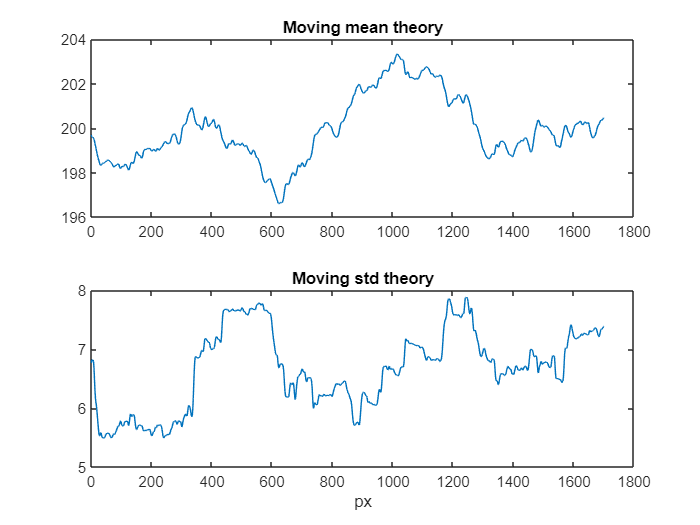

% 

w = 300;

thrMean = arrayfun(@(x) mean(theoryStruct{1}{1}.rawBarcode(x:x+w-1)),1:length(theoryStruct{1}{1}.rawBarcode)-w+1);
thrStd = arrayfun(@(x) std(theoryStruct{1}{1}.rawBarcode(x:x+w-1)),1:length(theoryStruct{1}{1}.rawBarcode)-w+1);

figure;tiledlayout(2,1);
nexttile
plot(thrMean)
title('Moving mean theory')
nexttile
plot(thrStd)
title('Moving std theory')
xlabel('px')

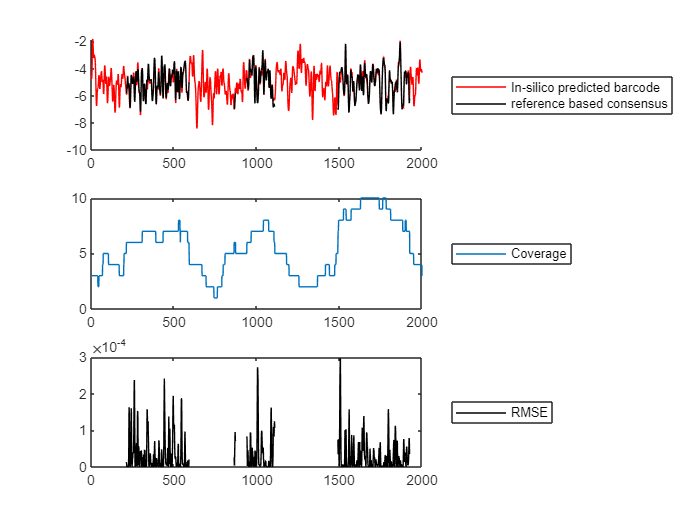

[outConsensus2, coverage2, pval3,f] = gen_reference_based_assembly(barcodeGen,synthStr{1},theoryStruct{1},'test11',inf);

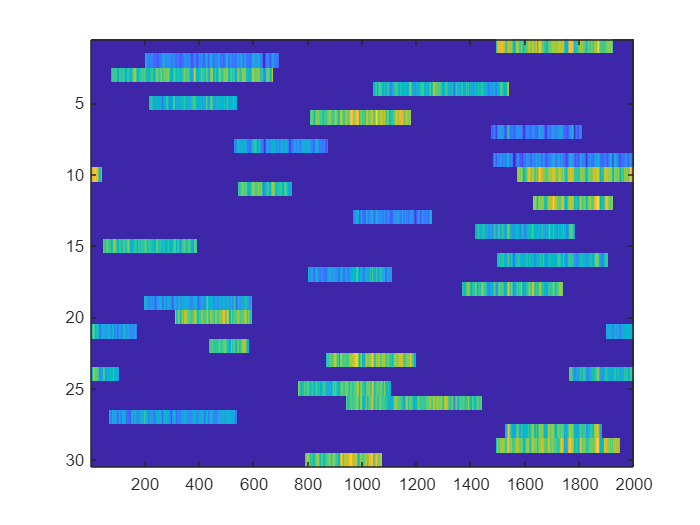

[outBarsCorrectLengthRescale] = barcodes_to_scaled(barcodeGen,synthStr{1},theoryStruct{1});

consensusToPlot1 = outBarsCorrectLengthRescale(2:end,:);

figure,imagesc(consensusToPlot1)

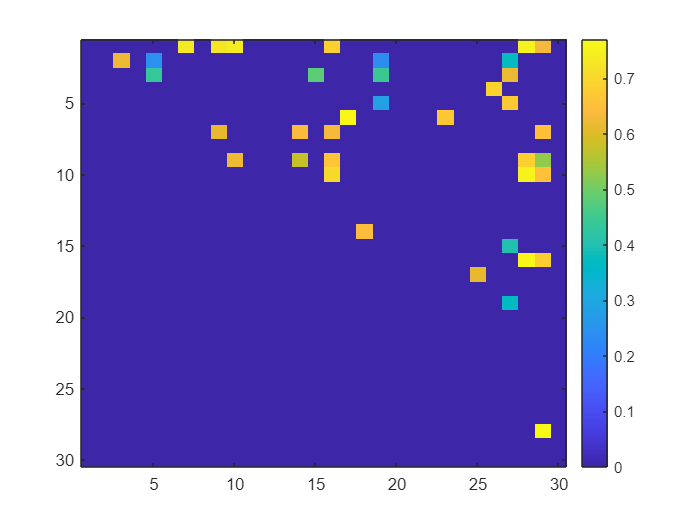

wmin = 300;
% pairwise compare
allscores = zeros(size(consensusToPlot1,1),size(consensusToPlot1,1));
for i=1:size(consensusToPlot1,1)-1
    for j=i+1:size(consensusToPlot1,1)        
        overlapPx = ~isnan(consensusToPlot1(i,:)).*~isnan(consensusToPlot1(j,:));
        if sum(overlapPx) > wmin %if overlap more than a given. Could also convert to Stouffer here
            allscores(i,j) = zscore(consensusToPlot1(i,logical(overlapPx)),1)*zscore(consensusToPlot1(j,logical(overlapPx)),1)'/sum(overlapPx);
        end
    end
end

figure,imagesc(allscores);colorbar

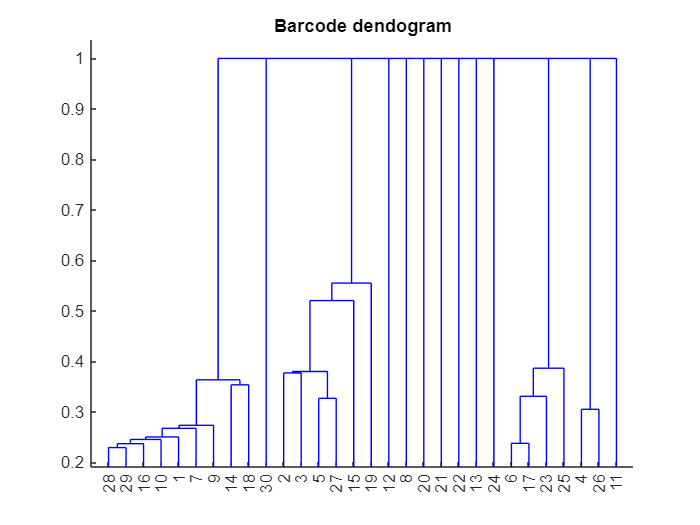



allscores2 = allscores'+allscores;
% square form
y = squareform(allscores2);


Z = linkage(1-y); % this links groups, but we also want to know which elements exactly are linked


% create groups for the scores
[groups,curElts] = consensus_groups(allscores,barcodeGen,Z);

figure % can plot the dendogram
dendrogram(Z); title('Barcode dendogram')

Example of consensus cluster step. We start with two barcodes

i = 1;
b1 = consensusToPlot1(curElts(i,1),:);
b2 = consensusToPlot1(curElts(i,2),:);

Calculate where they overlap

mask = logical( ~isnan(b1).*~isnan(b2));


Calculate means and standard deviations

mean1 = mean(b1(mask));
std1 = std(b1(mask),1);

mean2 = mean(b2(mask));
std2 = std(b2(mask),1);


% avg mean & avg std
newMean = (mean1+mean2)/2;
newStd = sqrt((std1^2+std2^2)/2);

stdRatio1 = newStd/std1;

stdRatio2 = newStd/std2;

% now update barcodes in the clusters 1 & 3

newGroup1 = (consensusToPlot1(groups{Z(i,1)},:))*stdRatio1 + newMean - mean1*stdRatio1;
newGroup2 = (consensusToPlot1(groups{Z(i,2)},:))*stdRatio2 + newMean - mean2*stdRatio2;

mean1 = mean(newGroup1(mask));
std1 = std(newGroup1(mask),1);

mean2 = mean(newGroup2(mask));
std2 = std(newGroup2(mask),1);

mean1,mean2,std1,std2

mean1 = 184.8626

mean2 = 184.8626

std1 = 7.9927

std2 = 7.9927

Calculate consensus in 3 different ways. "Old score" should be most accurate since it directly merges the barcodes without any z-scoring (and these are simple barcodes with Gaussian noise)

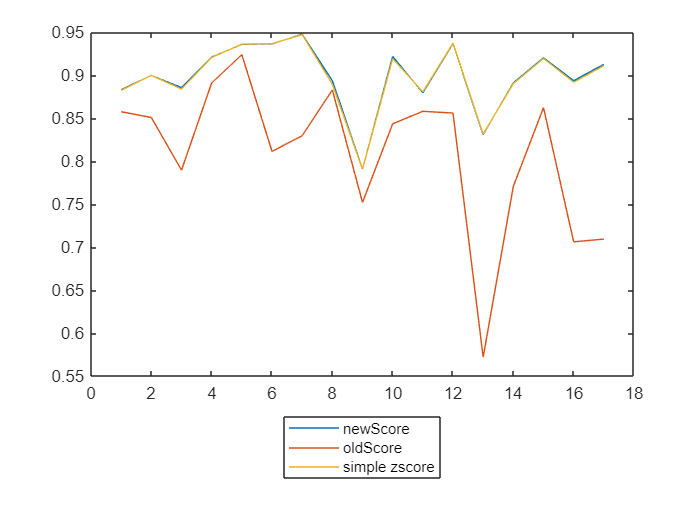


[scoreAlignedData,newScore,oldScore,oldScore2] = consensus_cluster(consensusToPlot1,Z,barcodeGen,curElts,groups,outBarsCorrectLengthRescale);

figure,plot(newScore);hold on;plot(oldScore);plot(oldScore2);legend({'newScore','oldScore','simple zscore'},'location','southoutside')